# **ROS Actions**

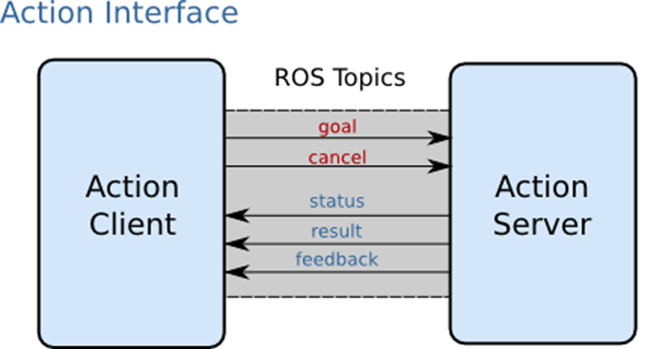

The [ActionServer](http://wiki.ros.org/actionlib)[ & ](http://wiki.ros.org/actionlib)[ActionClient](http://wiki.ros.org/actionlib) is the 3rd fundamental mode to communicate in ROS. It is similar to services.

The approach is **non-blocking **and useful for behavior that take long periods of time such as: 

- Navigation

- Manipulation ( typically used to execute manipulation tasks using time-stamped joint poses).

This notebook will show you how to create a ROS action client and execute the action. 

Action types must be set up beforehand with an action server running.

Connect to a ROS network. You must be connected to a ROS network to gather information about what actions are available. Replace `ipaddress` with your network address.

ipaddress = '192.168.203.133';
rosinit(ipaddress,11311)

The global ROS node is already initialized and connected to the master at URI "http://192.168.1.20:11311". If you want to restart the global node, call "rosshutdown" first.

List actions available on the network. The only action set up on this network is the `'/fibonacci'` action.

rosaction list

/fibonacci


### Action Messages

Action messages are composed of three properties which can be simple numbers or structures:

- goal

- result

- feedback 

### ROS Action Server

You must have set up the `'/fibonacci'` action type. To run this action server, use the following command on the ROS system:

`rosrun actionlib_tutorials fibonacci_server`

Callbacks...

### ROS Action Client

This ros action client command assumes an action server is already running. When called, `rosactionclient` will return 2 outputs: 

- an action client object and 

- an empty goal message of the same type as the action server. 

[actClient,goalMsg] = rosactionclient('/fibonacci','DataFormat','struct');

Wait for the action client to connect to the server.

waitForServer(actClient);

The fibonacci action will calculate the fibonacci sequence for a given order specified in the goal message. The goal message was returned when creating the action client and can be modified to send goals to the ROS action server. Set the order to an `int32` value of 8.

goalMsg.Order = int32(8);

In this case, it is important to cast the number to type int32 instead of a 'double'. 

### Sending the Action Goal

Send the goal and wait for its completion. Specify a timeout of 10 seconds to complete the action.

[resultMsg,resultState] = sendGoalAndWait(actClient,goalMsg,10);

rosShowDetails(resultMsg)

ans =     '
       MessageType :  actionlib_tutorials/FibonacciResult
       Sequence    :  [0, 1, 1, 2, 3, 5, 8, 13, 21]'


### Shutting Down

Disconnect from the ROS network.

rosshutdown

Shutting down global node /matlab_global_node_81947 with NodeURI http://192.168.203.1:54283/


clear

*Copyright 2020 The MathWorks, Inc.*